# MATLABから変数を変更

## 変数、RoadRunnerをクリーンアップ

if exist("rrApp", "var")
    if class(rrApp) == "roadrunner"
        rrApp.close();
    end
end
if exist("rrSim", "var")
    delete(rrSim);
end
close all;
clear;

## RoadRunnerをMATLABから起動

rrApp = roadrunner();

% 予め変数を作成したシナリオを開く
rrProjectPath = rrApp.status.Project.Filename;
copyfile("RRfiles/CutInAndSlowWithVariables.rrscenario",fullfile(rrProjectPath,"Scenarios/"))
openScenario(rrApp,"CutInAndSlowWithVariables")

## 一つのシナリオ変数を変更

サンプルシナリオ内にあらかじめ準備してあるシナリオ変数(”Gap”)にアクセス

name = "Gap";
value = 7; %[m]

% シナリオ変数の値を変更
setScenarioVariable(rrApp,name,value);

% シナリオ変数の値を取得
getScenarioVariable(rrApp,name)

ans = '7'

## シナリオ変数の作成

下記動画を参考にRoadRunnerで新規のシナリオ変数を作成下さい

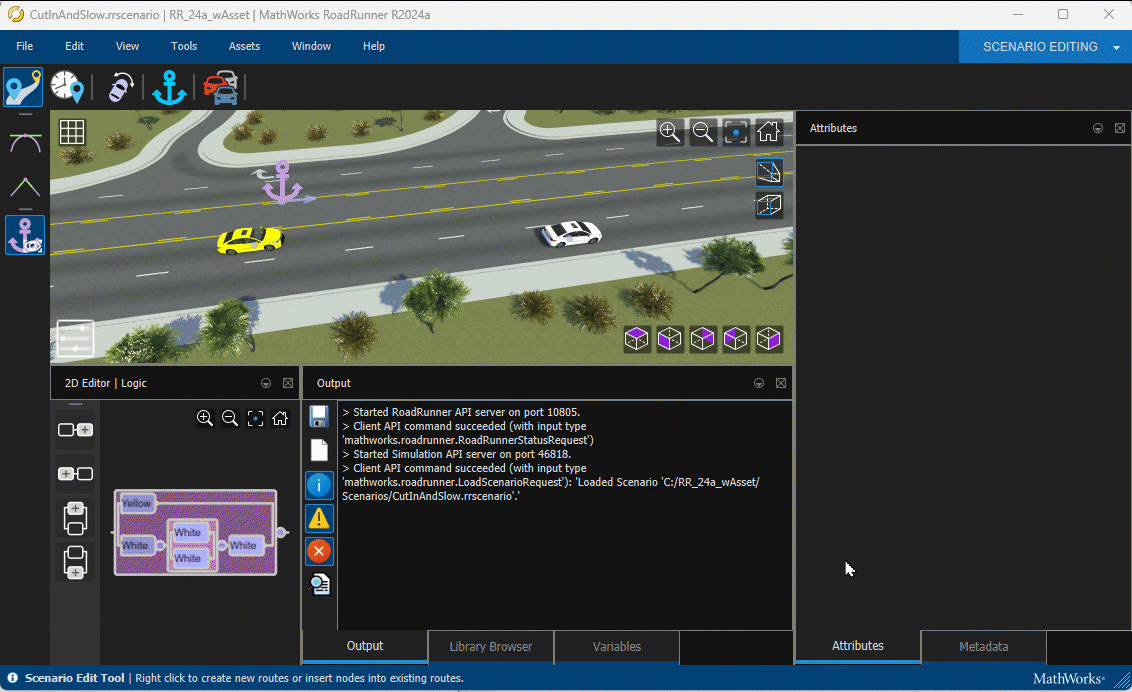

% 作成した変数値をMATLABから変更してみましょう。
% setScenarioVariable(rrApp,"作成した変数名","値"); % コメント解除して実行してみましょう

## 全てのシナリオ変数のリストを取得

開いているシナリオにどのような変数が定義されているかのリストを取得することも可能

% 全ての変数をRoadRunnerから取得
rrvars = getAllScenarioVariables(rrApp)

rrvars = 5×1 struct array with fields:
    Name
    Value
    TypedValue


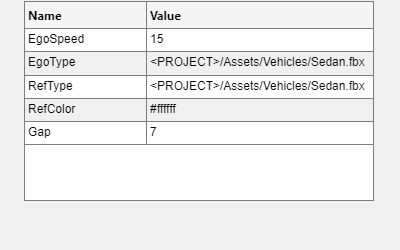

% 簡単なUIを使って変数値を変更
data = rmfield(rrvars,"TypedValue");
fig = uifigure('Position',[100 100 400 250]);
uit = uitable('Parent',fig,'Position',[25 50 350 200]);
uit.Data = struct2table(data);
uit.DisplayDataChangedFcn = @(src,event) updateScenario(src, rrApp);
uit.ColumnEditable = [false true];

## バリエーション生成

シナリオ変数へのアクセスはバリエーション生成にも活用可能

ここでは簡単なパラメータ振りと結果の可視化を実施

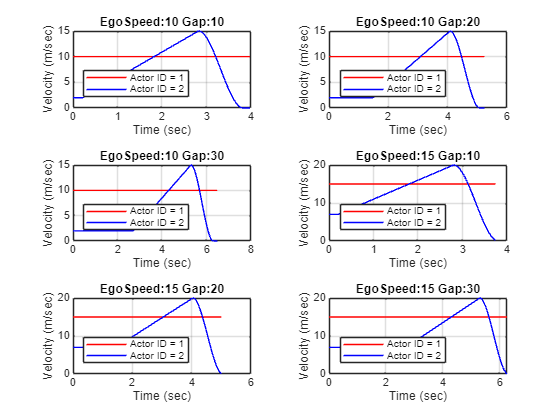

% パリエーション設定
egoSpeedList = [10 15];
gapList = [10 20 30];

rrSim = rrApp.createSimulation();

% シミュレーションのペーシングをOff
set(rrSim, "PacerStatus", "Off")

% logを取得する設定をONにする
set(rrSim,"Logging","on");

tiledlayout("flow");
for egoSpeed = egoSpeedList
    for gap = gapList

        % シナリオ変数の値を変更
        setScenarioVariable(rrApp,"EgoSpeed",egoSpeed);
        setScenarioVariable(rrApp,"Gap",gap);
        
        % シミュレーション実行
        set(rrSim,"SimulationCommand","Start");
        while strcmp(get(rrSim,"SimulationStatus"),"Running")
            pause(1);
        end
        
        % logを取得
        rrLog = get(rrSim,"SimulationLog");
        
        % 車両の速度を取得
        velocityAgent1 = get(rrLog,'Velocity','ActorID',1); % Actor1の速度取得
        velocityAgent2 = get(rrLog,'Velocity','ActorID',2); % Actor2の速度取得
        time = [velocityAgent1.Time];% Actor1の時刻取得
        
        % 車両の速度をプロット
        nexttile;
        helperPlotVelocity(time, velocityAgent1, velocityAgent2);
        title("EgoSpeed:"+string(egoSpeed)+" Gap:"+string(gap));

        % OpenSCENARIO XMLにエクスポート
        %filename = "EgoSpeed_" + string(egoSpeed) + "_Gap_" + string(gap);
        %exportScenario(rrApp,filename,"OpenSCENARIO");

    end
end

サポート関数

% uitable callback
function updateScenario(src, rrApp)
numParams = size(src.Data,1);
    for n = 1:numParams
        varname  = src.Data.Name{n};
        varvalue = src.Data.Value{n};
        setScenarioVariable(rrApp, varname, varvalue);
    end
end

% plotting velocity
function helperPlotVelocity(time, velocityAgent1, velocityAgent2)
    velMagAgent1 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent1);
    velMagAgent2 = arrayfun(@(x) norm(x.Velocity,2),velocityAgent2);

    % Plot the agent velocities with respect to simulation time using the plot function. Label the graph and the x and y axes.
    %figure
    plot(time,velMagAgent1,"r")
    hold on
    plot(time,velMagAgent2,"b")
    hold off
    grid on
    title("Agent Velocities from RoadRunner Scenario")
    ylabel("Velocity (m/sec)")
    xlabel("Time (sec)")
    legend("Actor ID = 1","Actor ID = 2",'Location','southwest')
end
